%% Reference Geometry
%Reference parameters
Lr = 0.152; % reference length [m]
Ar = pi * (Lr^2) / 4; % reference area [m^2]
        
%Nosecone parameters
logiva = 0.638; % nosecone length [m]
r0 = 0.152 / 2; % nosecone radius [m]

%Body parameters
l0 = 4.05; % rocket length [m]
lTubo = l0 - logiva; % fuselage length only [m]
Rs = 20 / 10^6; % RMC(?) roughness 20 um smooth paint

%Fin parameters
Cr = 0.254; %[m] root chord?
Ct = 0.229; %[m] tip chord?
span = 0.178; %[m] height?
pos_aletas = -l0 + (28.3+7.94-1.27)/100; % postion of fins measured from nosecone [m]
N = 3; % Number of fins
cant_angle_rad = degtorad(0); % fin cant angle [rad]

%Tail parameters
rt = 0.152 / 2; % tail radius [m]
h = 0.0794; % tail length [m]
r2 = 0.14 / 2; % smallest tail radius(?) [m]
pos_tail = -l0 + h; % tail position measured from nosecone

% Canards parameters 
% N_canard = 4;
% Cr_canard = 40 / 1000;
% Ct_canard = 40 / 1000; % "The tip is the size of the root to take advantage of the fact that the further away from the rocket, the greater the moment arm."
% span_canard = 80 / 1000;
% arm_canard = 10/1000; % Moment arm from fin to fuselage
% alfa_canard = degtorad(0); % Canard maximum angle of attack
% %pos_canard = -(558.29 + 40)/1000;
% pos_canard=x_cg; %assume fins are at CM - don't affect CP(?)

rail_angle = deg2rad(5)

rail_angle = 0.0873

% OR Simulation Output Data
or_data = readtable("project-jupiter-cc\Data\Borealis_flight_no_wind.csv")

or_data = 1300×55 table
    x_Time_s_    Altitude_m_    VerticalVelocity_m_s_    VerticalAcceleration_m_s__    TotalVelocity_m_s_    TotalAcceleration_m_s__    PositionEastOfLaunch_m_    PositionNorthOfLaunch_m_    LateralDistance_m_    LateralDirection___    LateralVelocity_m_s_    LateralAcceleration_m_s__    Latitude___    Longitude___    GravitationalAcceleration_m_s__    AngleOfAttack___    RollRate___s_    PitchRate___s_    YawRate___s_    Mass_g_    MotorMass_g_    LongitudinalMomentOfInertia_kg_m__    RotationalMomentOfInertia_kg_m__    CPLocation_cm_    CGLocation_cm_<

%% MCI
% Wet
I_xx_0 = or_data.RotationalMomentOfInertia_kg_m__(1);
I_yy_0 = or_data.LongitudinalMomentOfInertia_kg_m__(1);
I_zz_0 = I_yy_0 % rocket is axially symmetric

I_zz_0 = 56.3950

I_0 = [I_xx_0 0 0; 0 I_yy_0 0; 0 0 I_zz_0]; %kg*m^2
total_mass_0 = or_data.Mass_g_(1) / 1000; %g -> kg

% Dry
I_xx_d = or_data.RotationalMomentOfInertia_kg_m__(find(~isnan(or_data.RotationalMomentOfInertia_kg_m__), 1, 'last')); %moments of inertia become NaN at the end for some reason?
I_yy_d = or_data.LongitudinalMomentOfInertia_kg_m__(find(~isnan(or_data.LongitudinalMomentOfInertia_kg_m__), 1, 'last'));
I_zz_d = I_yy_d; % rocket is axially symmetric
I_d = [I_xx_d 0 0; 0 I_yy_d 0; 0 0 I_zz_d]; %kg*m^2
total_mass_d = or_data.Mass_g_(find(~isnan(or_data.Mass_g_), 1, 'last')) / 1000; % g -> kg

%% Input Time Series
sim_time = or_data.x_Time_s_; % s
F_thrust = or_data.Thrust_N_; % N assume thrust is perfectly aligned
OR_cg = -or_data.CGLocation_cm_ / 100; % centre of gravity over time (replace NaN with Last val)
% Do diff here since simulink may become unstable
mass = or_data.Mass_g_ / 1000; % g -> kg
Mdot = diff(mass) ./ diff(sim_time); % kg/s 1st discrete derivative
Mdot(end+1) = Mdot(end);
% Unfiltered quality is shit - need to see how simlink block behaves
Mdot = lowpass(Mdot, 0.1);

Cd = or_data.DragCoefficient___;
Mach = or_data.MachNumber___;

%% Reference Time Series
alt = or_data.Altitude_m_;
vel_ver = or_data.VerticalVelocity_m_s_;
drag = or_data.DragForce_N_;
crossrange = or_data.LateralDistance_m_;
v_crossrange = or_data.LateralVelocity_m_s_;
angle_vert_deg = 90 - or_data.VerticalOrientation_zenith____

angle_vert_deg =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


%% Cd vs Mach table
% Combine the two vectors into a 2-column matrix
data = [Mach(:), Cd(:)];  % Create a 2-column matrix (Mach, Cd)

% Sort the rows by the Mach number (first column)
sorted_data = sortrows(data, 1);  % Sort by Mach number (first column)

% Remove rows with duplicate Mach values (keep the first occurrence)
[~, unique_idx] = unique(sorted_data(:, 1), 'first');  % Find unique Mach numbers
unique_data = sorted_data(unique_idx, :);  % Keep only rows with unique Mach numbers

% Remove rows with any NaN values
unique_data = unique_data(~any(isnan(unique_data), 2), :);  % Remove rows with NaN

% Get the Cd value corresponding to Mach 0.3
mach_03_idx = find(unique_data(:, 1) >= 0.3, 1, 'first');  % Find the index of Mach closest to or equal to 0.3
Cd_at_03 = unique_data(mach_03_idx, 2);  % Cd value at Mach 0.3

% Replace Cd values for Mach < 0.3 with Cd value at Mach 0.3
unique_data(unique_data(:, 1) < 0.3, 2) = Cd_at_03;

% Final lookup table
lookup_table = unique_data;
CD_input = lookup_table(:, 1); % Mach #
CD_data = lookup_table(:, 2); % Cd

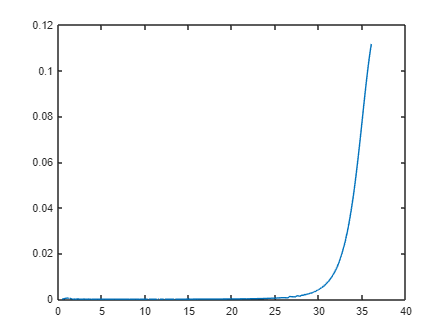

plot(sim_time, or_data.PitchDampingCoefficient___ ./ or_data.PitchRate___s_)